## **Name : Pitchaya Teerawongpairoj**

## Student ID : 6388133

## Section : 3

# **Triangulation Matting Project **

Read all 4 images

I1 = imread("bg1.png");
I2 = imread("bg2.png");
I3 = imread("fg1.png");
I4 = imread("fg2.png");

Display all 4 images

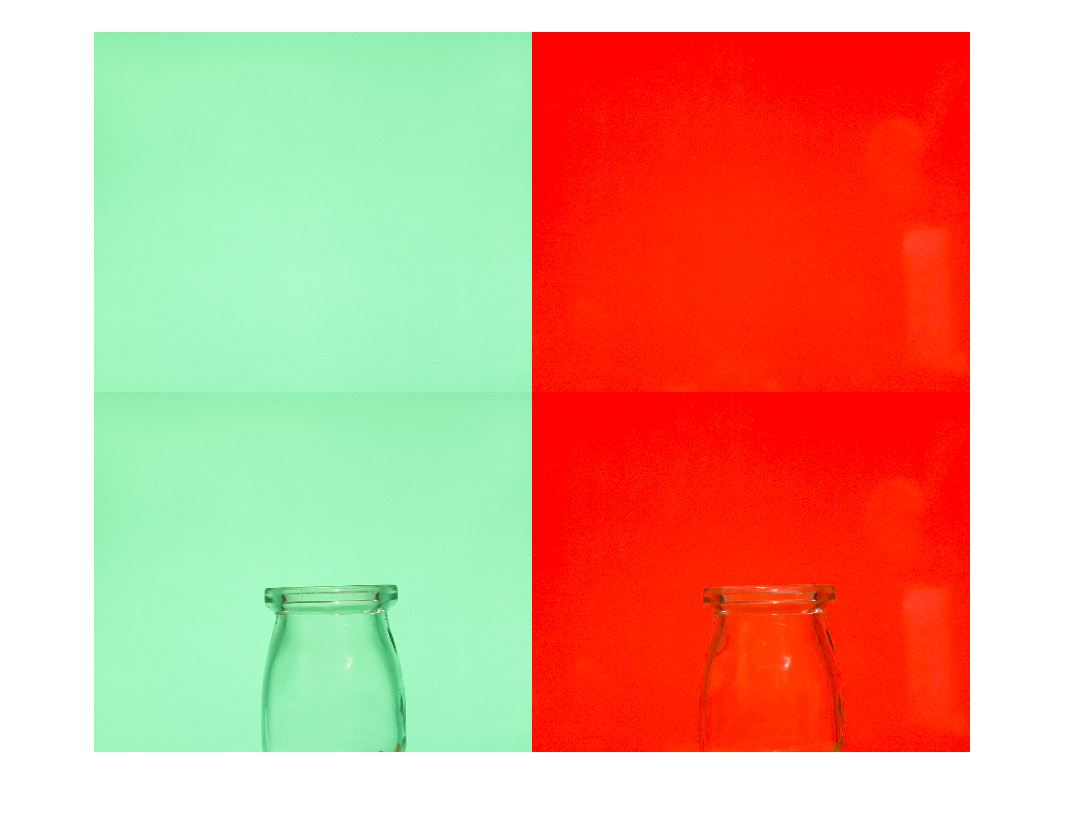

I = [I1 I2 ; I3 I4];
imshow(I)

Convert to double

d1=im2double(I1); %bg1
d2=im2double(I2); %bg2
d3=im2double(I3); %fg1
d4=im2double(I4); %fg2

Compute alpha

%red
r1=d1(:,:,1); %br1 Br1
r2=d2(:,:,1); %br2 Br2
r3=d3(:,:,1); %fr1 Cr1
r4=d4(:,:,1); %fr2 Cr2
%green
b1=d1(:,:,2); %bb1 Bb1
b2=d2(:,:,2); %bb2 Bb2
b3=d3(:,:,2); %fb1 Cb1
b4=d4(:,:,2); %fb2 Cb2
%blue
g1=d1(:,:,3); %bg1 Bg1
g2=d2(:,:,3); %bg2 Bg2
g3=d3(:,:,3); %fg1 Cg1
g4=d4(:,:,3); %fg2 Cg2
%compute alpha
CB=[(r3-r4).*(r1-r2)]+[(b3-b4).*(b1-b2)]+[(g3-g4).*(g1-g2)];
Bg=[(r1-r2).^2]+[(b1-b2).^2]+[(g1-g2).^2];
alpha=1-(CB./Bg);

Compute foreground colors of object from background 1 

%F=(C-[(1-alpha).*B])./alpha
red_foreground1   = (r3-[(1-alpha).*r1])./alpha;
blue_foreground1  = (b3-[(1-alpha).*b1])./alpha;
green_foreground1 = (g3-[(1-alpha).*g1])./alpha;
foreground1=cat(3,red_foreground1,blue_foreground1,green_foreground1);

Compute foreground colors of object from background 2

red_foreground2   = (r4-[(1-alpha).*r2])./alpha;
blue_foreground2  = (b4-[(1-alpha).*b2])./alpha;
green_foreground2 = (g4-[(1-alpha).*g2])./alpha;
foreground2=cat(3,red_foreground2,blue_foreground2,green_foreground2);

Display the extracted foreground object / matte from background 1 and 2

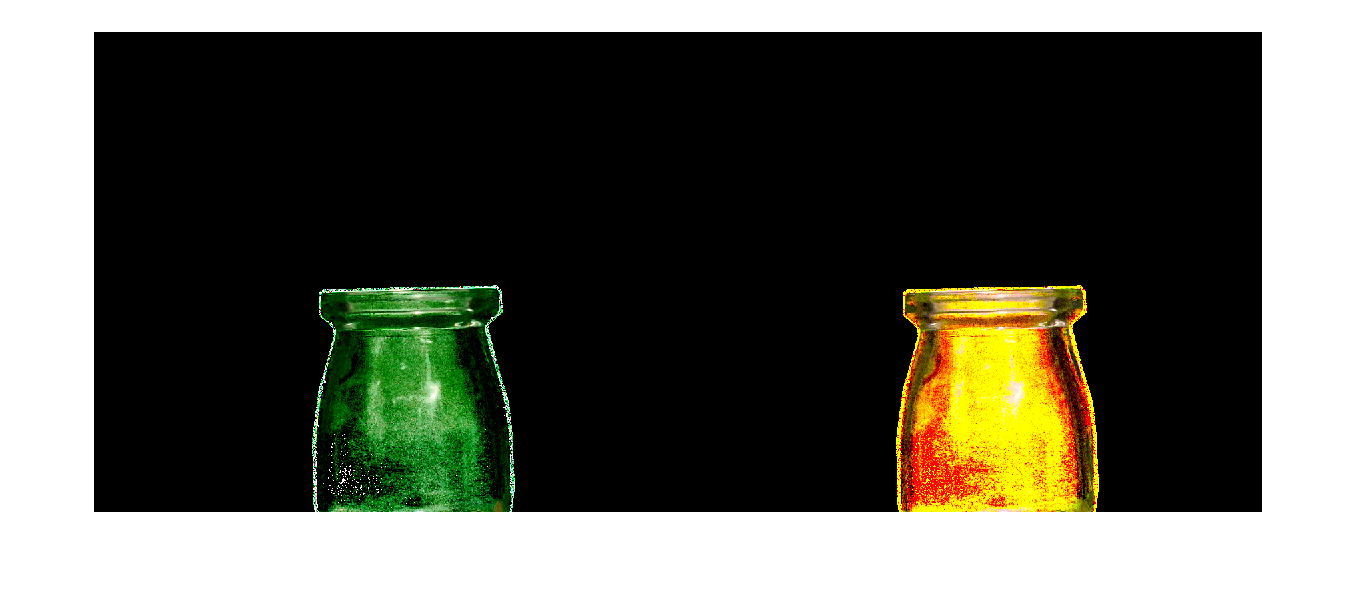

imshowpair(foreground1,foreground2,"montage")

Perform the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

foreground1(isnan(foreground1))=255;
foreground2(isnan(foreground2))=255;
h=size(foreground1,1);
w=size(foreground1,2);
w_img=255*ones(h,w,3,"uint8");
d_w_img=im2double(w_img);
new1=alpha.*foreground1+((1-alpha)).*d_w_img;
new2=alpha.*foreground2+((1-alpha)).*d_w_img;

Display the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

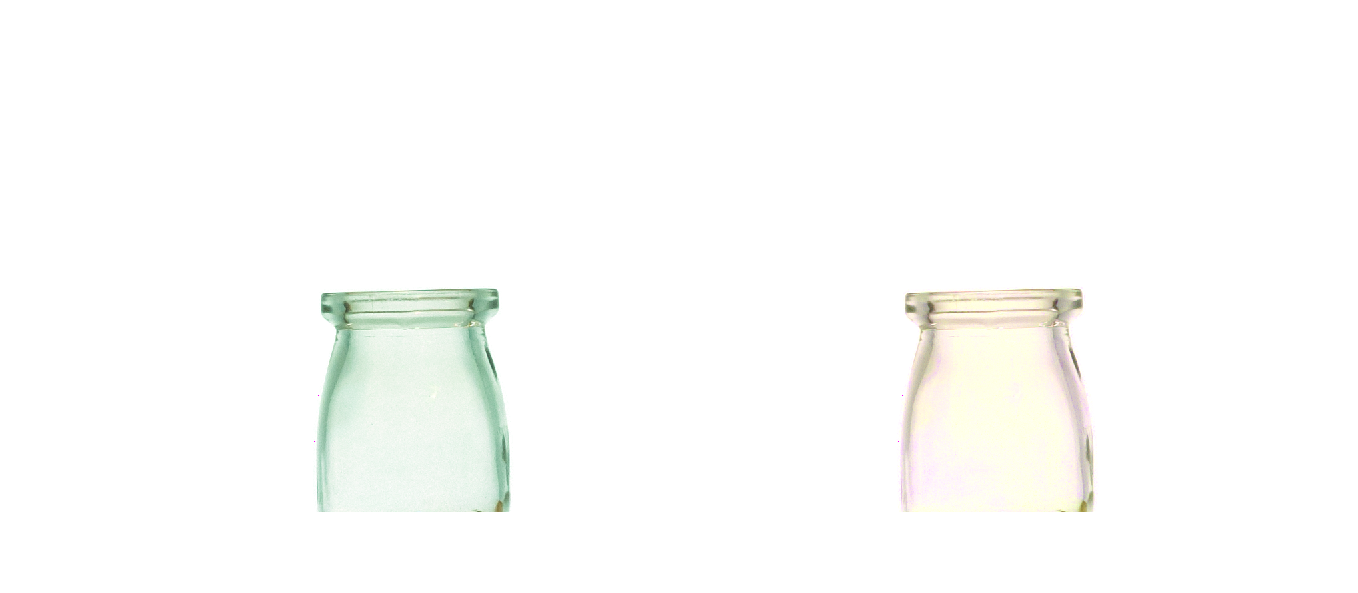

imshowpair(new1,new2,"montage")

Read new background image to do the composition and display it.

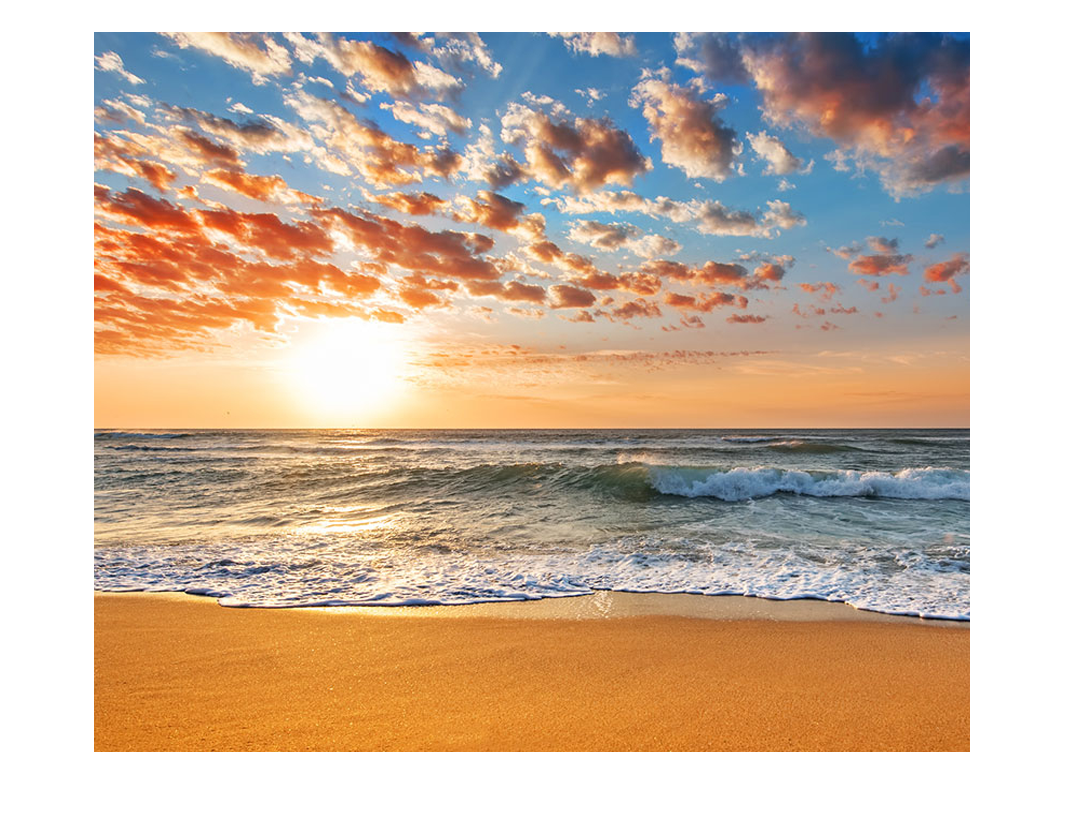

new_bg=imread("new_bg1.png");
imshow(new_bg)

Perform the composition of extracted foreground object from background 1 and 2 with the new background image

back=im2double(new_bg);
new_pic1=alpha.*foreground1+((1-alpha)).*back;
new_pic2=alpha.*foreground2+((1-alpha)).*back;

Display the composition of extracted foreground object from background 1 and 2 with the new background image

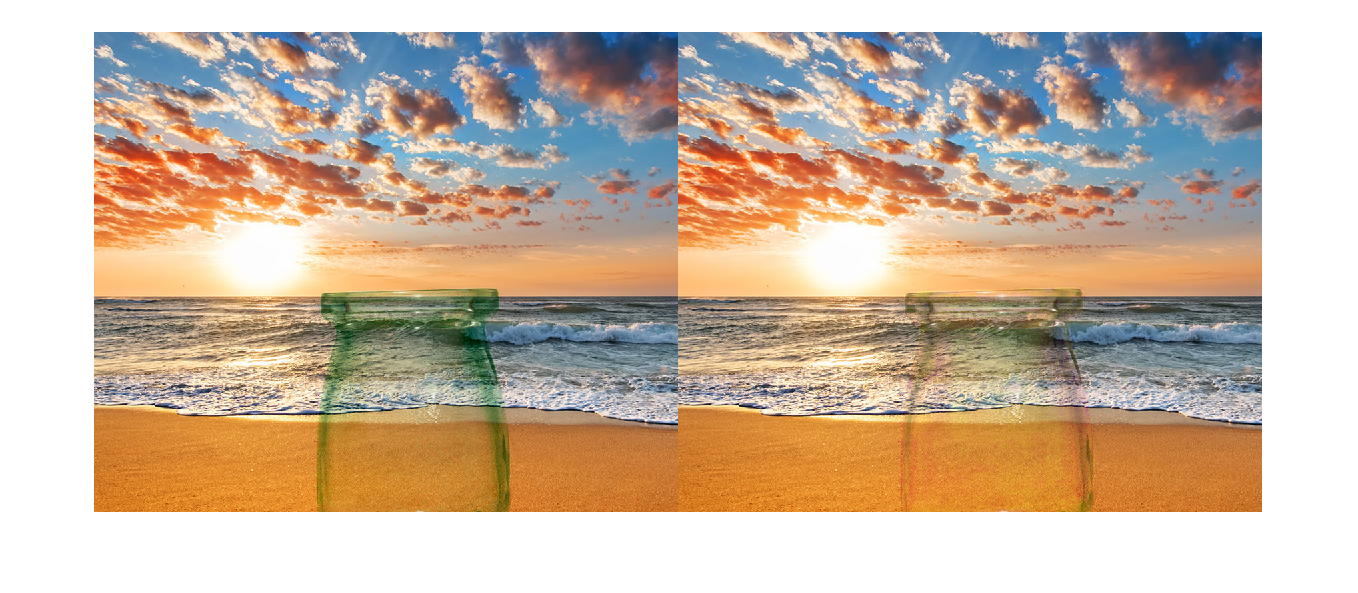

imshowpair(new_pic1,new_pic2,"montage")